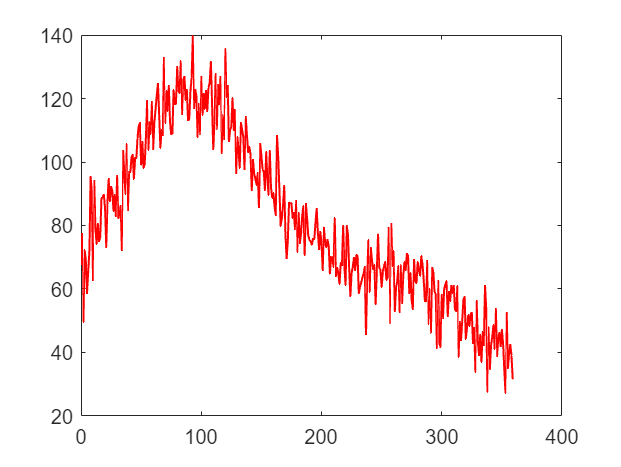

% creat a Direction Index(DI) original data combine with two gaussian distribution and a
% constant of offset
% parameters and response function are shown below
R_p = 100;
R_n = 40;
ang_p = 90;
ang_n = ang_p + 180;
ang = 0:359;
sig = 70;

Rsp = R_p * exp(-0.5*(ang-ang_p).^2/sig^2) + R_n * exp(-0.5*(ang-ang_n).^2/sig^2);
s0 = sig/10;
offset = R_p/5 + s0*randn(1,length(Rsp));
Rsp = offset + Rsp;

plot(ang,Rsp,'r','LineWidth',1);

% assume that each parameters' prior probability fit uniform distribution 
% liklihood(R_p,R_n,ang_p,s)

vrp = linspace(1.2*R_p-0.5*sig,1.2*R_p+0.5*sig,50);
vrn = linspace(R_n+R_p/5-0.5*sig,R_n+R_p/5+0.5*sig,50);
vang = linspace(0,180,360);
vangn = vang + 180;
vsig = linspace(sig-30,sig+30,100);
lik = zeros(length(vrp),length(vrn),length(vang),length(vsig));

for i = 1:length(vrp)
    for j = 1:length(vrn)
        for k = 1:length(vang)  
            for h = 1:length(vsig) 
                vrsp = vrp(i) * exp(-0.5*(ang-vang(k)).^2/vsig(h)^2) + vrn(j) * exp(-0.5*(ang-vangn(k)).^2/vsig(h)^2);
                lik(i,j,k,h) = exp(-0.5*sum((Rsp - vrsp).^2)/s0.^2);% log form of lik function
            end
        end 
    end
end
lik = lik/sum(lik,'all');
[M,I] = max(lik,[],'all'); % get maximum liklihood of parameters value and get the index of parameters

% most possible value of parameters
[i,j,k,h] = ind2sub(size(lik),I);
R_p = vrp(i) - R_p/5,

R_p = 97.8571

R_n = vrn(j) - R_p/5,

R_n = 39.7143

vang(k),

ans = 85.2368

vsig(h),

ans = 73.9394

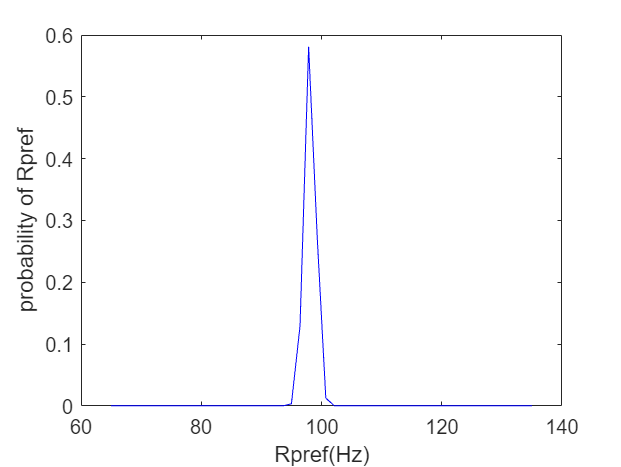

%plot each parameter's posterior probability distribution
p_rp = sum(sum(sum(lik,4),3),2);
p_rp = p_rp/sum(p_rp);
p_rn = sum(sum(sum(lik,4),3),1);
p_rn = p_rn/sum(p_rn);
p_ang = squeeze(sum(sum(sum(lik,4),2),1));
p_ang = p_ang/sum(p_ang);
p_sig = squeeze(sum(sum(sum(lik,3),2),1));
p_sig = p_sig/sum(p_sig);

plot(vrp-20,p_rp,'b'),
xlabel("Rpref(Hz)"),
ylabel("probability of Rpref"),

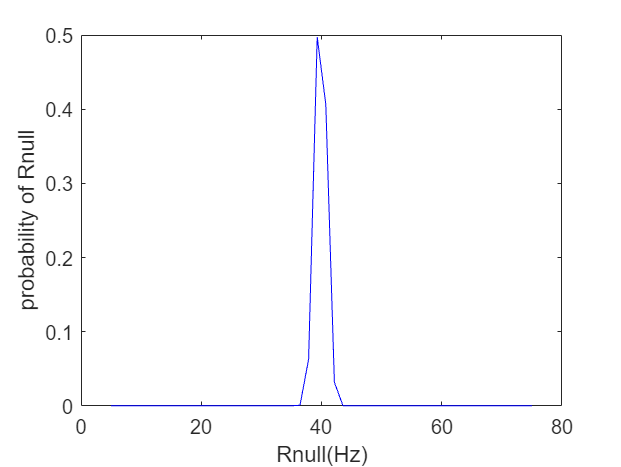


plot(vrn-20,p_rn,'b'),
xlabel("Rnull(Hz)"),
ylabel("probability of Rnull"),

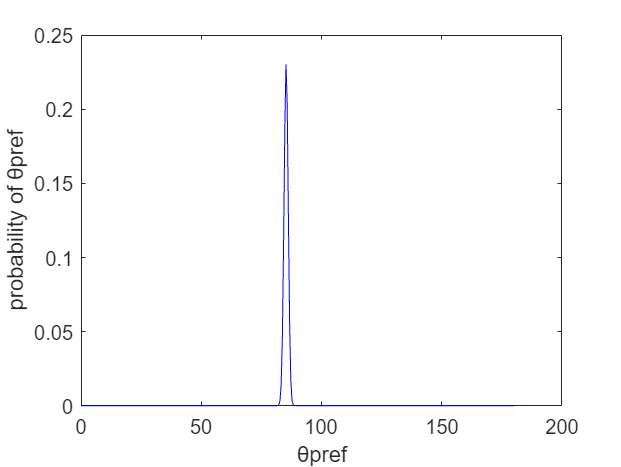


plot(vang,p_ang,'b'),
xlabel("θpref"),
ylabel("probability of θpref"),

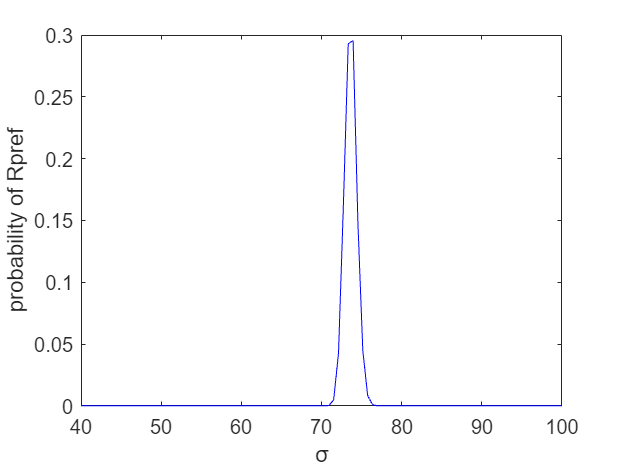


plot(vsig,p_sig,'b'),
xlabel("σ"),
ylabel("probability of Rpref"),